# Radioactive decay & Bateman equation

### Prerequisites

#### Radioactive decay

In mathematics radioactive decay of a substance 1 to a stable substance 2 is defined as:

$-\frac{dN}{N}=\lambda\,dt$           (1)

with $\lambda$ being the decay constant and $N$ the number of particles.

The solution of the first order differential equation is:

$N(t)=N_0\,\mathrm{e}^{-\lambda t}$       (2)

$N(t)$ is the number of particles at the time $t$.

$N_0$ is the number of particles at the time $t=0$.

Example:

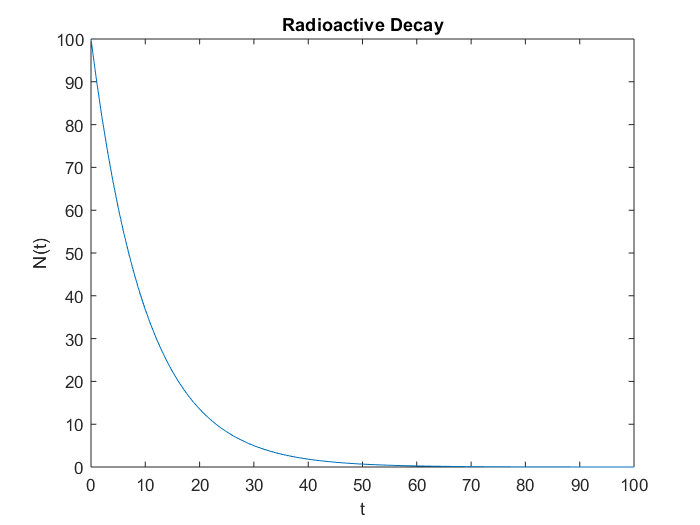

lambda = 0.1;           % decay constant
N0 = 100;               % number of particles at t = 0
t = 0 : 100;            % t in s, min, h, d, a...
Nt = N0*exp(-lambda*t);

% plot section
plot(t,Nt);
title('Radioactive Decay')
ylabel('N(t)');
xlabel('t');

#### Half-life

The time $t$ after that half or 50% of $N_0$ is decayed is called half-life $t_{1/2}$.

Halfe-life can be obtained from (2) with $N(t)=N_0/2$:

$\frac{N_0/2}{N_0}=\frac{1}{2}=\mathrm{e}^{-\lambda\,t_{1/2}}
$         (3)

$\mathrm{log}\Big (\frac{1}{2} \Big )=-\lambda \,t_{1/2}$           (4)

$t_{1/2}=\frac{\mathrm{log}(2)}{\lambda}$                  (5)

$\lambda$ can be replaced by $t_{1/2}$ by solving (5) for $\lambda$:

$\lambda=\frac{\mathrm{log}(2)}{t_{1/2}}$                     (6)

With (6) equation (2) becomes:

$N(t)=N_0\,\mathrm{e}^{\Bigg (-\frac{\log(2)}{t_{1/2}}\cdot t \Bigg )}$     (7)

Example:

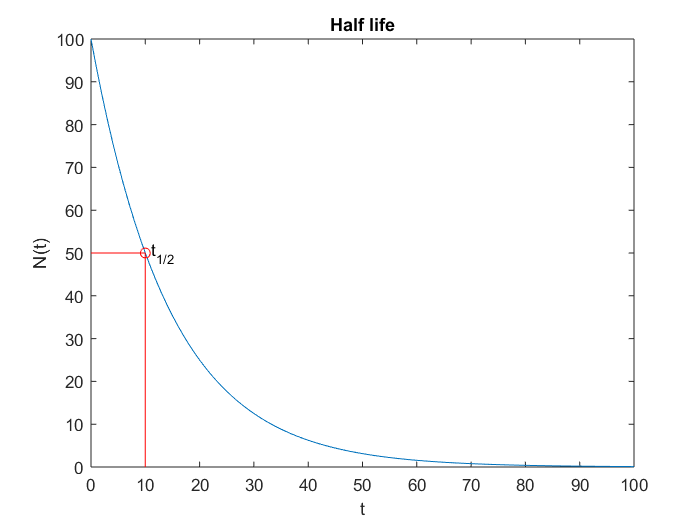

t_12 = 10;       % half-life t(1/2) in s, min, h, d, a...
N0 = 100;        % number of particles at t = 0
t = 0 : t_12*10; % t in s, min, h, d, a...
Nt = N0*exp(-(log(2)/t_12)*t);

% plot section
plot(t,Nt);
ylabel('N(t)');
xlabel('t');
title('Half life')
hold on;

% emphasize half-life t(1/2)
stem(t_12,N0*exp(-(log(2))),'Color','r');
line([0 t_12], [N0*exp(-(log(2))) N0*exp(-(log(2)))],'Color','r');
text(t_12+t_12*0.1,N0*exp(-(log(2))),'t_{1/2}');
hold off;

#### Activity

The number of particles $N$ can be replaced by the Activity $A$ which is defined as number of decays per unit time of a radioactive sample. $A$ is more common than $N$ since it is proportional to the number of counts per time that instruments for radiation detection can measure. A Geiger counter is an example for such a device. The unit for $A$ is $\mathrm{s}^{-1}$ or Bq.

The activity is defined as:

$A(t)=-\frac{dN}{dt}=\lambda N(t)$   (8)

and (2) can be transfomed to:

$A(t)=A_0\,\mathrm{e}^{-\lambda t}$               (9)

### Bateman and how to solve a system of differential equations with MATLAB

The first section showed a simple example of an exponential decay of one compound. In reality the decay of a substance is often more complex. 

When an active substance decays it usually takes several steps with several active substances in between before a stable isotope is formed. An active substance can even decay into two or more new components (branching) which are active as well before decaying to stable isotopes in the end.

This all can be formulated with several differential equations. Harry Bateman was the first who offered an analytical solution to this mathematical problem. 

#### The product of a simple radioactive decay

When a radioactive compound decays it should give a stable product. The reaction can be formulated as: $1 \overset{\lambda_1}\rightarrow 2$.

The decay of 1 is:


$$$\frac{dN_1}{dt}=-\lambda_1 N_1$$
 

The formation of 2 can be described as:


$$$\frac{dN_2}{dt}=\lambda_1 N_1$$


In MATLAB this can be done by (symbolic math toolbox needed):

syms N1(t) N2(t) l1 N0;            % l = lambda
eq_1 = diff(N1(t),t) == -l1*N1(t); % decay of 1
eq_2 = diff(N2(t),t) ==  l1*N1(t); % formation of 2

Solving this system of differential equations can be done as follows. Conditions are $N_1(t=0)=N_0$ and $N_2(t=0)=0$:

sol = dsolve ([eq_1 eq_2, N1(0) == N0 N2(0) == 0]); 

The solutions are:

disp('Solutions of the differential equations:')

Solutions of the differential equations:


N1 = sol.N1

$$N1 = N_{0}\,{\mathrm{e}}^{-l_{1}\,t}$$

N2 = sol.N2

$$N2 = N_{0}-N_{0}\,{\mathrm{e}}^{-l_{1}\,t}$$

For demonstration purposes it is easier to use relative (rel) instead of absolute values. This can be achieved by dividing the solutions by $N_0$:

disp('Solutions of the differential equations divided by N0:')

Solutions of the differential equations divided by N0:


N1rel = sol.N1/N0

$$N1rel = {\mathrm{e}}^{-l_{1}\,t}$$

N2rel = sol.N2/N0;
N2rel = simplify(N2rel)

$$N2rel = 1-{\mathrm{e}}^{-l_{1}\,t}$$

Finally the solutions are:


$$\frac{N_1}{N_0}=e^{- \lambda_1t}$$



$$\frac{N_2}{N_0}=1-e^{- \lambda_1t}$$


Cs-138 decays to the stable Ba-138 isotope, half-life is 33.4 min. The symbolic constants will be replaced by real values:

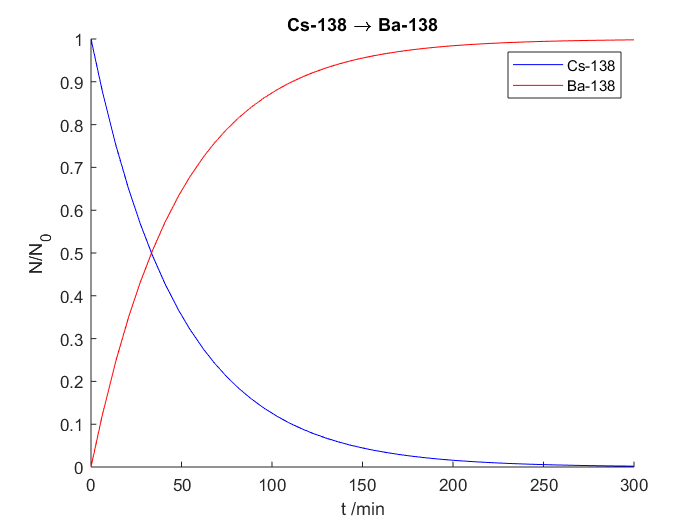

clf;
l1_v = log(2)/33.4; % insert t(1/2) for 1, l=log(2)/t(1/2)

% substitute symbolic l1 with a real value for l1, l1_v
N1s = subs(N1rel, [l1], [l1_v]);
N2s = subs(N2rel, [l1], [l1_v]);

t = [0 300];

% plot section
hold on;
fplot(N1s,t,'Color','b');
fplot(N2s,t,'Color','r');
ylabel('N/N_0');
xlabel('t /min');
legend('Cs-138','Ba-138');
title('Cs-138 \rightarrow Ba-138');
hold off;

#### Substance 1 decays to 2 and 2 is active as well, 3 is stable

A somewhat more realistic case: $1  \overset{\lambda_1} \rightarrow 2  \overset{\lambda_2} \rightarrow 3$

1 decays to 2, but 2 decays as well to 3, 3 is a stable isotope.

The differential equations that describe the above situation are:

$$\frac{dN_1}{dt}=-\lambda_1 N_1$                  decay of 1

$$\frac{dN_2}{dt}=-\lambda_2 N_2 + \lambda_1N_1$       decay of 2 + formation of 2 from 1

To keep it simple, the formation of 3 is ignored. Conditions are $N_1(t=0)=N_0$ and $N_2(t=0)=0$. $N$ will be replaced with $A$ $(A = N \lambda)$. $A$ will be divided by $A_0$ to get relative instead of absolute activities.

syms N1(t) N2(t) l1 l2 N0 A0;                 % l = lambda
eq_1 = diff(N1(t),t) == -l1*N1(t);            % decay of 1
eq_2 = diff(N2(t),t) == -l2*N2(t) + l1*N1(t); % decay of 2 + formation of 2

% solve the system of differential equations
sol = dsolve ([eq_1 eq_2, N1(0) == N0 N2(0) == 0]);

% divide by N0 for relative values
disp('multiply with l to transform N to A:')

multiply with l to transform N to A:


A1 = sol.N1*l1

$$A1 = N_{0}\,l_{1}\,{\mathrm{e}}^{-l_{1}\,t}$$

A2 = sol.N2*l2

$$A2 = -l_{2}\,\left(\frac{N_{0}\,l_{1}\,{\mathrm{e}}^{-l_{1}\,t}}{l_{1}-l_{2}}-\frac{N_{0}\,l_{1}\,{\mathrm{e}}^{-l_{2}\,t}}{l_{1}-l_{2}}\right)$$

disp('replace N0*l1 with A0:')

replace N0*l1 with A0:


A1 = subs(A1, [N0*l1],[A0])

$$A1 = A_{0}\,{\mathrm{e}}^{-l_{1}\,t}$$

A2 = subs(A2, [N0*l1],[A0])

$$A2 = -l_{2}\,\left(\frac{A_{0}\,{\mathrm{e}}^{-l_{1}\,t}}{l_{1}-l_{2}}-\frac{A_{0}\,{\mathrm{e}}^{-l_{2}\,t}}{l_{1}-l_{2}}\right)$$

disp('divide by A0 to get relative Activities A_n_rel:')

divide by A0 to get relative Activities A_n_rel:


A1rel = A1/A0

$$A1rel = {\mathrm{e}}^{-l_{1}\,t}$$

A2rel = A2/A0;
A2rel = simplify(A2rel,'Steps',40)

$$A2rel = -\frac{l_{2}\,\left({\mathrm{e}}^{-l_{1}\,t}-{\mathrm{e}}^{-l_{2}\,t}\right)}{l_{1}-l_{2}}$$

The solutions are:


$$\frac{A_1}{A_0}=e^{- \lambda_1t}$$



$$\frac{A_2}{A_0}=-\frac{\lambda_2}{\lambda_1 - \lambda_2}(e^{- \lambda_1t} - e^{- \lambda_2t})$$


Since there are two active (radioactive) substances now, the overall activity is the sum of both activities:


$$A_{sum}=\frac{A_1}{A_0}+\frac{A_2}{A_0}$$


A simple radiation detector would count something proportional to the sum of both activities $A_{sum}$.

A practical example is the decay of Mo-99 to Tc-99m. Half-life for Mo-99 is 65.94 h and forTc-99m 6.01 h. A non-branching decay is assumed.

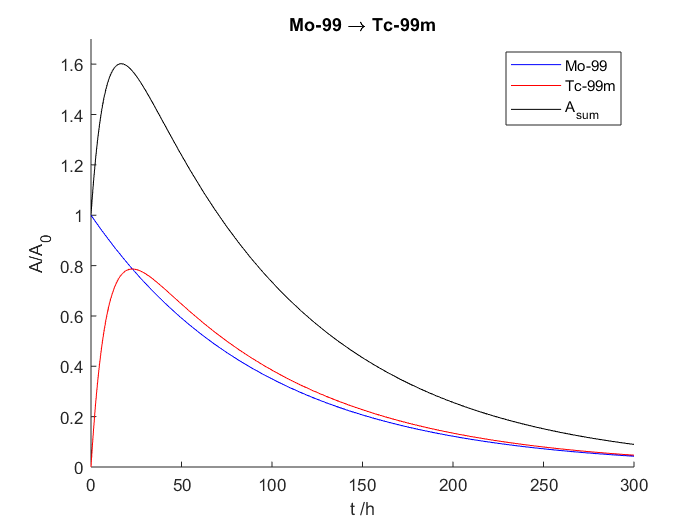

clf;
l1_v = log(2)/65.94;  % insert t(1/2) for 1, l=log(2)/t(1/2)
l2_v = log(2)/6.01;   % insert t(1/2) for 2, l=log(2)/t(1/2)

% substitute symbolic l1 and l2 with a real value for l1 and l2
% l1_v and l2_v
A1s = subs(A1rel, [l1], [l1_v]);
A2s = subs(A2rel, [l1,l2], [l1_v,l2_v]);

A_sum = A1s + A2s;    % sum of A1 + A2
t = [0 300];

% plot section
hold on;
fplot(A1s,t,'Color','b');
fplot(A2s,t,'Color','r');
fplot(A_sum,t,'Color','black');
ylabel('A/A_0');
xlabel('t /h');
ylim([0 1.7]);
legend('Mo-99','Tc-99m','A_{sum}');
title('Mo-99 \rightarrow Tc-99m');
hold off;

The overall activity ($A_{sum}$) is higher than the activity of the individual components ($A_1/A_0$ and $A_2/A_0$). Looking at the plot a question arises: When, at which time, is the maximum activity?

One option to obtain the maxima is to find the first derivative of the functions, set the derivatives equal to zero and solve for $t$. In MATLAB this can be done with the "diff" and "solve" instructions.

syms N1(t) N2(t) l1 l2 N0 A0;                 % l = lambda
eq_1 = diff(N1(t),t) == -l1*N1(t);            % decay of 1
eq_2 = diff(N2(t),t) == -l2*N2(t) + l1*N1(t); % decay of 2 + formation of 2

% solve the system of differential equations
sol = dsolve ([eq_1 eq_2, N1(0) == N0 N2(0) == 0]);

% multiply with l to transform N to A
A1 = sol.N1*l1;
A2 = sol.N2*l2;

% replace N0*l1 with A0
A1 = subs(A1, [N0*l1],[A0]);
A2 = subs(A2, [N0*l1],[A0]);

%divide by A0 to get relative Activities A_n_rel
A1rel = A1/A0;
A2rel = A2/A0;
A2rel = simplify(A2rel,'Steps',40);

% l1_v ans l2_v
l1_v = log(2)/65.94;  % insert t(1/2) for 1, l=log(2)/t(1/2)
l2_v = log(2)/6.01;   % insert t(1/2) for 2, l=log(2)/t(1/2)

% substitute symbolic l1 and l2 with a real value for l1 and l2
% l1_v and l2_v
A1s = subs(A1rel, [l1], [l1_v]);
A2s = subs(A2rel, [l1,l2], [l1_v,l2_v]);

A_sum = A1s + A2s;    % sum of A1 + A2

% first derivatives of A1s and A_sum
dA2s = diff(A2s);
dA_sum = diff(A_sum);

% solve the equations for t
t_A2_max = solve(dA2s == 0,t);
t_A_sum_max = solve(dA_sum == 0,t);

% display the values
disp('Time to reach maximum activities:')

Time to reach maximum activities:


t_A2_max = vpa(t_A2_max,4) 

$$t\_A2\_max = 22.85$$

t_A_sum_max = vpa(t_A_sum_max,4)

$$t\_A\_sum\_max = 16.68$$

disp('Maximum activities:')

Maximum activities:


A2_max = vpa(subs(A2s,t,t_A2_max),4)

$$A2\_max = 0.7865$$

A_sum_max = vpa(subs(A_sum,t,t_A_sum_max),4)

$$A\_sum\_max = 1.602$$

The maximum activity for Tc-99m is reached after 22.85 h and the maximum overall activity after 16.68 h. Plot of the results:

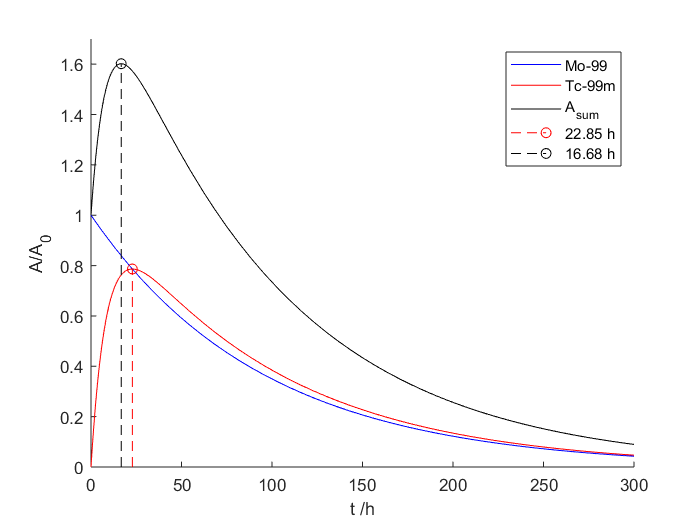

clf;
t = [0 300];

% plot section
hold on;
fplot(A1s,t,'Color','b');
fplot(A2s,t,'Color','r');
fplot(A_sum,t,'Color','black');
ylabel('A/A_0');
xlabel('t /h');
ylim([0 1.7]);

% add t_A2_max and t_A_sum_max to the plot
stem(t_A2_max,A2_max,'--','Color','red','Marker','o');
stem(t_A_sum_max,A_sum_max,'--','Color','black','Marker','o');
legend('Mo-99','Tc-99m','A_{sum}','22.85 h','16.68 h');
hold off;

Tc-99m is a medical radiotracer. But its half-life is rather short. Instead the mother nuclid Mo-99 is supplied to hospitals and Tc-99m is extracted from Mo-99. Therefore it is important to know when the Tc-99m activity reaches its maximum.

#### Branching: 1 decays to 2 and 3 

Branching is a radioactive disintegration that occurs via two or more decay processes. In a simple branching process, 1 split into compounds 2 and 3 with a certain branching ratio $r$: $2 \overset{\lambda_1, r_{1,2}} \longleftarrow 1  \overset{\lambda_1,  r_{1,3}} \longrightarrow 3$

The system of differential equations can be formulated as follows (2 and 3 are considered to be stable):

$$\frac{dN_1}{dt}=-\lambda_1 N_1$                  decay of 1

$$\frac{dN_2}{dt}= r_{1,2}\;\lambda_1\;N_1$             formation of 2 from 1

$$\frac{dN_3}{dt}= r_{1,3}\;\lambda_1\;N_1$             formation of 3 from 1

syms N1(t) N2(t) N3(t) l1 r12 r13 N0;    % l = lambda, r_xy = branching ratio
eq_1 = diff(N1(t),t) == -l1*N1(t);       % decay of 1
eq_2 = diff(N2(t),t) ==  r12*l1*N1(t);   % formation of 2 from 1
eq_3 = diff(N3(t),t) ==  r13*l1*N1(t);   % formation of 3 from 1

% solve the system of differential equations
sol = dsolve ([eq_1 eq_2 eq_3, N1(0) == N0 N2(0) == 0 N3(0) == 0]);

% solutions of the differential equations
N1 = sol.N1;
N2 = sol.N2;
N3 = sol.N3;

% divide by N0 to get relative values
N1rel = N1/N0

$$N1rel = {\mathrm{e}}^{-l_{1}\,t}$$

N2rel = N2/N0;
N2rel = simplify(N2rel,'Steps',40)

$$N2rel = -r_{12}\,\left({\mathrm{e}}^{-l_{1}\,t}-1\right)$$

N3rel = N3/N0;
N3rel = simplify(N3rel,'Steps',40)

$$N3rel = -r_{13}\,\left({\mathrm{e}}^{-l_{1}\,t}-1\right)$$

The solutions are:


$$\frac{N_1}{N_0}=e^{- \lambda_1t}$$



$$\frac{N_2}{N_0}=-r_{1,2}(e^{- \lambda_1t}-1)$$



$$\frac{N_3}{N_0}=-r_{1,3}(e^{- \lambda_1t}-1)$$


For example 56.3% of I-126 decays to Te-126  and 43.7% to Xe-126. The half-life of I-126 is 12.93 d. 

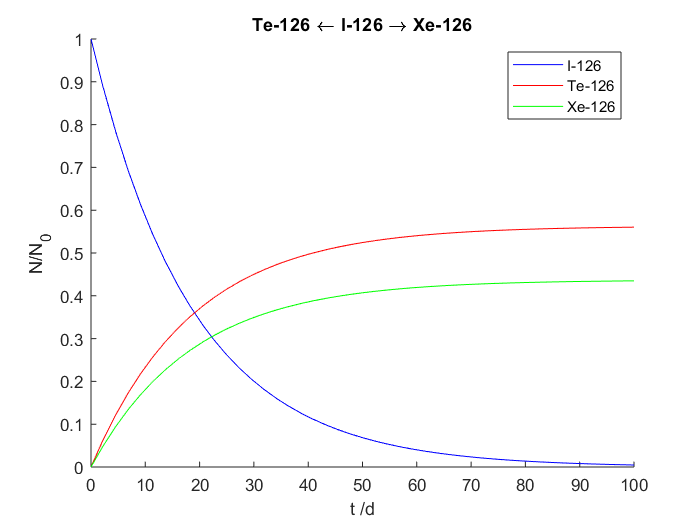

clf;
l1_v = log(2)/12.93;  % insert t(1/2) for 1, l=log(2)/t(1/2)
r12_v = 0.563;        % insert branching ratio 1 -> 2
r13_v = 0.437;        % insert branching ratio 1 -> 3

% substitute symbolic l1 and r_xy with real values for l1, l1_v amd r_xy_v
N1s = subs(N1rel, [l1], [l1_v]);
N2s = subs(N2rel, [l1 r12], [l1_v r12_v]);
N3s = subs(N3rel, [l1 r13], [l1_v r13_v]);

t = [0 100];

% plot section
hold on;
fplot(N1s,t,'Color','b');
fplot(N2s,t,'Color','r');
fplot(N3s,t,'Color','g');
ylabel('N/N_0');
xlabel('t /d');
legend('I-126','Te-126','Xe-126');
title('Te-126 \leftarrow I-126 \rightarrow Xe-126');
hold off;

### More complex problems of radioactive decay

Now all one should know to solve more complex problems of radioactive decay are at hand.

#### A complex theoretical example

Compound 1 decays by branching to 2 and 3. 2 is stable, 3 decays further by branching to 4 and 5. 5 decays to 6 which further decays to stable 7. 4 decays to 7.


$$2 \overset{\lambda_1, r_{1,2}} \longleftarrow 1  \overset{\lambda_1,  r_{1,3}} \longrightarrow 3$$



$$4 \overset{\lambda_3, r_{3,4}} \longleftarrow 3  \overset{\lambda_3,  r_{3,5}} \longrightarrow 5$$



$$4  \overset{\lambda_4} \longrightarrow 7$$



$$5  \overset{\lambda_5} \longrightarrow 6  \overset{\lambda_6} \longrightarrow 7$$


The system of differential equations can be formulated as follows:

$$\frac{dN_1}{dt}=-\lambda_1 N_1$                       decay of 1

$$\frac{dN_2}{dt}=r_{1,2}\;\lambda_1\;N_1$                   formation of stable 2 from 1

$$\frac{dN_3}{dt}=-\lambda_3 N_3 + r_{1,3}\;\lambda_1\;N_1$      decay of 3 and formation of 3 from 1

$$\frac{dN_4}{dt}=-\lambda_4 N_4 + r_{3,4}\;\lambda_3\;N_3$      decay of 4 and formation of 4 from 3

$$\frac{dN_5}{dt}=-\lambda_5 N_5 + r_{3,5}\;\lambda_3\;N_3$      decay of 5 and formation of 5 from 3

$$\frac{dN_6}{dt}=-\lambda_6 N_6 + \lambda_5 N_5$            decay of 6 and formation of 6 from 5

$$\frac{dN_7}{dt}= \lambda_4 N_4 + \lambda_6 N_6$               formation of stable 7 from 4 and 6

MATLAB:

syms N1(t) N2(t) N3(t) N4(t) N5(t) N6(t) N7(t) l1 l3 l4 l5 l6 r12 r13 r34 r35 N0; % l = lambda, r_xy = branching ratio
eq_1 = diff(N1(t),t) == -l1*N1(t);                  % decay of 1
eq_2 = diff(N2(t),t) ==  r12*l1*N1(t);              % formation of stable 2 from 1
eq_3 = diff(N3(t),t) == -l3*N3(t) + r13*l1*N1(t);   % decay of 3 and formation of 3 from 1
eq_4 = diff(N4(t),t) == -l4*N4(t) + r34*l3*N3(t);   % decay of 4 and formation of 4 from 3
eq_5 = diff(N5(t),t) == -l5*N5(t) + r35*l3*N3(t);   % decay of 5 and formation of 5 from 3
eq_6 = diff(N6(t),t) == -l6*N6(t) + l5*N5(t);       % decay of 6 and formation of 6 from 5
eq_7 = diff(N7(t),t) ==  l4*N4(t) + l6*N6(t);       % formation of stable 7 from 4 and 6

% solve the system of differential equations
sol = dsolve ([eq_1 eq_2 eq_3 eq_3 eq_4 eq_5 eq_6 eq_7, N1(0)==N0 N2(0)==0 N3(0)==0 N4(0)==0 N5(0)==0 N6(0)==0 N7(0)==0]);

% solutions of the differential equations
N1 = sol.N1;
N2 = sol.N2;
N3 = sol.N3;
N4 = sol.N4;
N5 = sol.N5;
N6 = sol.N6;
N7 = sol.N7;

% divide by N0 to get relative values
N1rel = N1/N0

$$N1rel = {\mathrm{e}}^{-l_{1}\,t}$$

N2rel = N2/N0;
N2rel = simplify(N2rel,'Steps',40)

$$N2rel = -r_{12}\,\left({\mathrm{e}}^{-l_{1}\,t}-1\right)$$

N3rel = N3/N0;
N3rel = simplify(N3rel,'Steps',40)

$$N3rel = -\frac{l_{1}\,r_{13}\,\left({\mathrm{e}}^{-l_{1}\,t}-{\mathrm{e}}^{-l_{3}\,t}\right)}{l_{1}-l_{3}}$$

N4rel = N4/N0;
N4rel = simplify(N4rel,'Steps',40)

$$N4rel = \frac{l_{1}\,l_{3}\,r_{13}\,r_{34}\,{\mathrm{e}}^{-l_{1}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{1}-l_{4}\right)}-\frac{l_{1}\,l_{3}\,r_{13}\,r_{34}\,{\mathrm{e}}^{-l_{3}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{3}-l_{4}\right)}+\frac{l_{1}\,l_{3}\,r_{13}\,r_{34}\,{\mathrm{e}}^{-l_{4}\,t}}{\left(l_{1}-l_{4}\right)\,\left(l_{3}-l_{4}\right)}$$

N5rel = N5/N0;
N5rel = simplify(N5rel,'Steps',40)

$$N5rel = \frac{l_{1}\,l_{3}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{1}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{1}-l_{5}\right)}-\frac{l_{1}\,l_{3}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{3}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{3}-l_{5}\right)}+\frac{l_{1}\,l_{3}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{5}\,t}}{\left(l_{1}-l_{5}\right)\,\left(l_{3}-l_{5}\right)}$$

N6rel = N6/N0;
N6rel = simplify(N6rel,'Steps',40)

$$N6rel = \frac{l_{1}\,l_{3}\,l_{5}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{3}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{3}-l_{5}\right)\,\left(l_{3}-l_{6}\right)}-\frac{l_{1}\,l_{3}\,l_{5}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{1}\,t}}{\left(l_{1}-l_{3}\right)\,\left(l_{1}-l_{5}\right)\,\left(l_{1}-l_{6}\right)}-\frac{l_{1}\,l_{3}\,l_{5}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{5}\,t}}{\left(l_{1}-l_{5}\right)\,\left(l_{3}-l_{5}\right)\,\left(l_{5}-l_{6}\right)}+\frac{l_{1}\,l_{3}\,l_{5}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{6}\,t}}{\left(l_{1}-l_{6}\right)\,\left(l_{3}-l_{6}\right)\,\left(l_{5}-l_{6}\right)}$$

N7rel = N7/N0;
N7rel = simplify(N7rel,'Steps',40)

$$N7rel = r_{13}\,\left(r_{34}+r_{35}\right)-\frac{l_{1}\,l_{3}\,r_{13}\,r_{34}\,{\mathrm{e}}^{-l_{4}\,t}}{\left(l_{1}-l_{4}\right)\,\left(l_{3}-l_{4}\right)}-\frac{l_{3}\,r_{13}\,{\mathrm{e}}^{-l_{1}\,t}\,\left({l_{1}}^{2}\,l_{4}\,r_{34}-l_{1}\,l_{4}\,l_{5}\,r_{34}-l_{1}\,l_{4}\,l_{6}\,r_{34}-l_{1}\,l_{5}\,l_{6}\,r_{35}+l_{4}\,l_{5}\,l_{6}\,r_{34}+l_{4}\,l_{5}\,l_{6}\,r_{35}\right)}{\left(l_{1}-l_{3}\right)\,\left(l_{1}-l_{4}\right)\,\left(l_{1}-l_{5}\right)\,\left(l_{1}-l_{6}\right)}+\frac{l_{1}\,r_{13}\,{\mathrm{e}}^{-l_{3}\,t}\,\left({l_{3}}^{2}\,l_{4}\,r_{34}-l_{3}\,l_{4}\,l_{5}\,r_{34}-l_{3}\,l_{4}\,l_{6}\,r_{34}-l_{3}\,l_{5}\,l_{6}\,r_{35}+l_{4}\,l_{5}\,l_{6}\,r_{34}+l_{4}\,l_{5}\,l_{6}\,r_{35}\right)}{\left(l_{1}-l_{3}\right)\,\left(l_{3}-l_{4}\right)\,\left(l_{3}-l_{5}\right)\,\left(l_{3}-l_{6}\right)}+\frac{l_{1}\,l_{3}\,l_{6}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{5}\,t}}{\left(l_{1}-l_{5}\right)\,\left(l_{3}-l_{5}\right)\,\left(l_{5}-l_{6}\right)}-\frac{l_{1}\,l_{3}\,l_{5}\,r_{13}\,r_{35}\,{\mathrm{e}}^{-l_{6}\,t}}{\left(l_{1}-l_{6}\right)\,\left(l_{3}-l_{6}\right)\,\left(l_{5}-l_{6}\right)}$$

Plot of the solution.

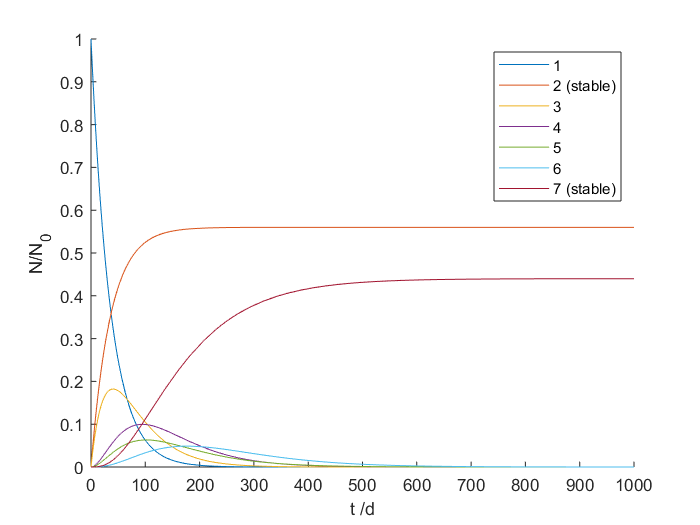

clf;
l1_v = log(2)/25;  % insert t(1/2) for 1, l=log(2)/t(1/2)
l3_v = log(2)/32;  % insert t(1/2) for 3, l=log(2)/t(1/2)
l4_v = log(2)/44;  % insert t(1/2) for 4, l=log(2)/t(1/2)
l5_v = log(2)/55;  % insert t(1/2) for 5, l=log(2)/t(1/2)
l6_v = log(2)/60;  % insert t(1/2) for 6, l=log(2)/t(1/2)
r12_v = 0.56;      % insert branching ratio 1 -> 2
r13_v = 0.44;      % insert branching ratio 1 -> 3
r34_v = 0.64;      % insert branching ratio 3 -> 4
r35_v = 0.36;      % insert branching ratio 3 -> 5

% substitute symbolic l_n and r_xy with real values for l_n, l_n_v and r_xy_v
N1s = subs(N1rel, [l1], [l1_v]);
N2s = subs(N2rel, [l1 r12], [l1_v r12_v]);
N3s = subs(N3rel, [l1 l3 r13], [l1_v l3_v r13_v]);
N4s = subs(N4rel, [l1 l3 l4 r13 r34], [l1_v l3_v l4_v r13_v r34_v]);
N5s = subs(N5rel, [l1 l3 l5 r13 r35], [l1_v l3_v l5_v r13_v r35_v]);
N6s = subs(N6rel, [l1 l3 l5 l6 r13 r35], [l1_v l3_v l5_v l6_v r13_v r35_v]);
N7s = subs(N7rel, [l1 l3 l4 l5 l6 r13 r34 r35], [l1_v l3_v l4_v l5_v l6_v r13_v r34_v r35_v]);

t = [0 1000];

% plot section
hold on;
ylim([0 1]);
fplot(N1s,t);
fplot(N2s,t);
fplot(N3s,t);
fplot(N4s,t);
fplot(N5s,t);
fplot(N6s,t);
fplot(N7s,t);
ylabel('N/N_0');
xlabel('t /d');
legend('1','2 (stable)','3','4','5','6','7 (stable)');
hold off;